# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 26-Feb-2022 23:55:13

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = imageInputLayer([227 227 3],"Name","imageinput_2");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([129 8 1],"Name","imageinput_1")
    stftLayer("Name","stft")
    batchNormalizationLayer("Name","batchnorm_1")
    lstmLayer(512,"Name","lstm_1")
    lstmLayer(512,"Name","lstm_2")
    fullyConnectedLayer(10,"Name","fc_1")
    reluLayer("Name","relu")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    concatenationLayer(2,2,"Name","concat")
    batchNormalizationLayer("Name","batchnorm_2")
    lstmLayer(128,"Name","lstm_3")
    lstmLayer(128,"Name","lstm_4")
    fullyConnectedLayer(10,"Name","fc_2")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"imageinput_2","concat/in2");
lgraph = connectLayers(lgraph,"relu","concat/in1");

## Plot Layers

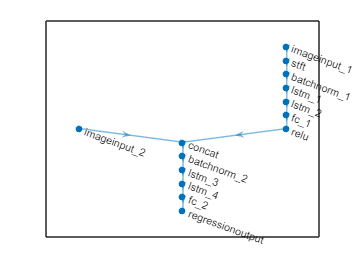

plot(lgraph);